clear;
for i = 1:3
    for j = 1:3
        for k = 1:5
            A(i,j,k) = i + 2*j;
        end
    end
end

A

A = A(:,:,1) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,2) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,3) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,4) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,5) =

     3     5     7
     4     6     8
     5     7     9



B = reshape(A,[],5)

B =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     7     7     7     7     7
     8     8     8     8     8
     9     9     9     9     9



clear;
M = 10;
N = ceil(M/2);
orig_dom_X = linspace(-pi/2,pi/2,M);
orig_dom_Y = linspace(-pi/2,pi/2,N)

orig_dom_Y =    -1.5708   -0.7854         0    0.7854    1.5708


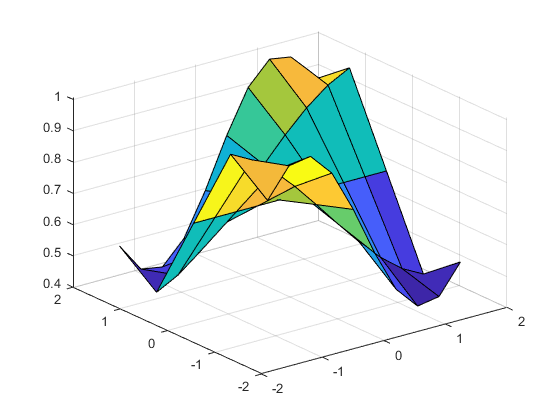

[X,Y] = ndgrid(orig_dom_X,orig_dom_Y);

for i = 1:88
    m = rand;
    b = rand;
    A(:,:,i) = m*sin(X.*Y) + b;
end
surf(X,Y,A(:,:,5))


s = size(A);

B = reshape(A,[],s(end))

B =     0.8678    0.2066    0.6199    1.4398    0.9021    1.0611    0.6004    0.8351    0.1546    0.4719    1.1119    1.2361    0.8436    1.0281    0.5044    0.2334    0.5708    0.6706    1.4520    0.5344    0.9091    0.9314    1.0318    0.6237    0.2694    0.5342    0.7582    0.5073    1.1077    0.7948    1.0377    0.6254    0.4110    0.4887    0.8226    1.2711    1.0269    1.4544    0.9956    0.9639    1.0411    0.8198    0.8058    0.5502    1.1286    0.2740    0.1912    1.4013    1.2460    0.2951
    1.1242    0.2907    0.7935    1.7126    0.9941    1.2607    0.6009    1.1086    0.2042    0.5044    1.2747    1.4071    1.0772    1.0901    0.5288    0.3377    0.7599    0.8546    1.7471    0.7559    1.1598    1.0168    1.0957    0.7830    0.2955    0.7684    0.7971    0.7341    1.2993    1.0683    1.3061    0.6537    0.5752    0.6946    0.9706    1.4602    1.2234    1.7428    1.2797    0.9871    1.2956    0.8417    0.9206    0.5559    1.2443    0.4068    0.2634    1.6535    1.3743    0

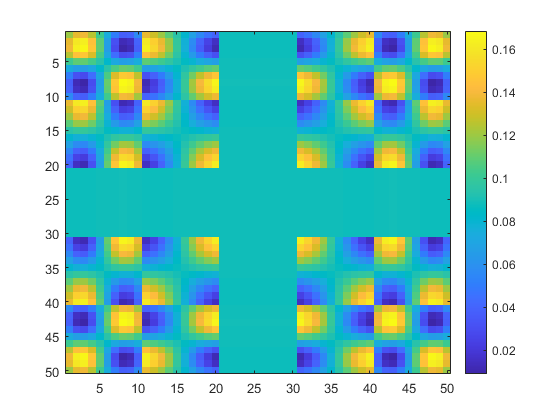

B = B';

C_B = cov(B);
imagesc(C_B)
colorbar


% 'If I reshape this^ image correctly, I should get a 4D array that varies smoothly on each of its 4 axes'
disp(['If I reshape this^ image correctly,' newline 'I should get a 4D array that ' newline 'varies smoothly on each of its 4 axes.'])

If I reshape this^ image correctly,
I should get a 4D array that 
varies smoothly on each of its 4 axes.



disp(['A good way to check if I''m reshaping it' newline 'properly or not would be to' newline 'reshape, interpolate, reshape, and plot.'])

A good way to check if I'm reshaping it
properly or not would be to
reshape, interpolate, reshape, and plot.



C = reshape(C_B,M,N,M,N);
disp('size of C')

size of C


size(C)

ans =     10     5    10     5



N_h = 2*N;
M_h = 2*M;
new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(-pi/2,pi/2,M_h);
new_dom_X2 = linspace(-pi/2,pi/2,N_h);
new_dom_Y2 = linspace(-pi/2,pi/2,M_h);

[X1_h,Y1_h,X2_h,Y2_h] = ndgrid(new_dom_X1,new_dom_Y1,new_dom_X2,new_dom_Y2);
C_high_def = interpn(orig_dom_X,orig_dom_Y,orig_dom_X,orig_dom_Y,C,X1_h,Y1_h,X2_h,Y2_h);
C_B_high_def = reshape(C_high_def,N_h*M_h,N_h*M_h);



imagesc(C_B_high_def)
colorbar

disp('This is awesome and meta.')